clear variables
load('Tests/PC_TT_completion_test/Tline_completion/tl_completion_samples.mat')


training_idx = training_idx(1:700,:);
training_xi = training_xi(1:700,:);
training_outs = training_outs(1:700,:);

[~,d] = size(training_xi);
[n_samples,n_outs] = size(training_outs);
m = 3;
N = (m+1)*ones(d,1);
r = 3;

y_init = cell(n_outs,1);
for i = 1:n_outs
    y_init{i} = formRank1Tensor(ref_out(i),r1_outs(:,i),m,d);
end

tic
[vouts_Riemannian,PC_coefficients,training_err,test_err] = ...
    pc_collocation_tensor_completion(training_idx,training_outs,y_init,testing_xi,m,'Hermite','TT-Riemannian',3,5e-3,false);
toc

Elapsed time is 20.021437 seconds.


disp(norm(vouts_Riemannian-testing_outs,'fro')/norm(testing_outs,'fro'))

    0.0117



training_xi2 = training_xi2(1:9920,:);
training_outs2 = training_outs2(1:9920,:);
tic
vouts_total = pc_collocation_total(training_xi2,training_outs2,testing_xi,m ,'Hermite');
toc

Elapsed time is 24.241918 seconds.


disp(norm(vouts_total-testing_outs,"fro")/norm(testing_outs,"fro"))

    0.0175



load('Tests/PC_TT_completion_test/Tline_completion/ttcross_outs.mat')
disp(norm((vouts_tt_cross)-testing_outs,"fro")/norm(testing_outs,"fro"))

    0.0190



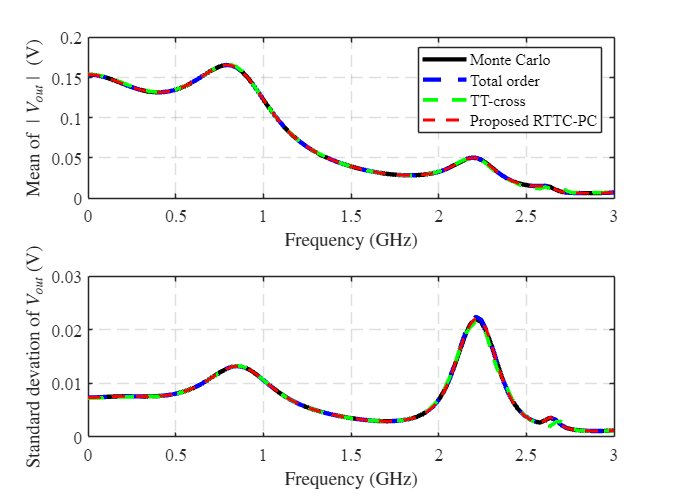

close all

fpoints = linspace(0,3e9,100);

vout_mean0 = mean(abs(testing_outs));
vout_sigma0 = std((testing_outs));
vout_plus_3sigma0 = (vout_mean0+3*vout_sigma0); 
vout_minus_3sigma0 = (vout_mean0-3*vout_sigma0);

vout_mean1 = mean(abs(vouts_Riemannian));
vout_sigma1 = std((vouts_Riemannian));
vout_plus_3sigma1 = (vout_mean1+3*vout_sigma1);
vout_minus_3sigma1 = (vout_mean1-3*vout_sigma1);

vout_mean2 = mean(abs(vouts_total));
vout_sigma2 = std((vouts_total));
vout_plus_3sigma2 = (vout_mean2+3*vout_sigma2);
vout_minus_3sigma2 = (vout_mean2-3*vout_sigma2);

vout_mean3 = mean(abs(vouts_tt_cross));
vout_sigma3 = std((vouts_tt_cross));
vout_plus_3sigma3 = (vout_mean3+3*vout_sigma3);
vout_minus_3sigma3 = (vout_mean3-3*vout_sigma3);

scale = 1e9;

f = figure(2);
subplot(2,1,1);
hold on
plot(fpoints/scale,vout_mean0,'k-','LineWidth',3);
plot(fpoints/scale,vout_mean2,'b--','LineWidth',3);
plot(fpoints/scale,vout_mean3,'g--','LineWidth',2.5);
plot(fpoints/scale,vout_mean1,'r--','LineWidth',2);
legend('Monte Carlo ','Total order','TT-cross','Proposed RTTC-PC')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid V_{out} \mid $ (V)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


subplot(2,1,2);
hold on
plot(fpoints/scale,vout_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,vout_sigma2,'b--','LineWidth',3);
% plot(fpoints/scale,vout_sigma3,'b--','LineWidth',3);
plot(fpoints/scale,vout_sigma3,'g--','LineWidth',2.5);
plot(fpoints/scale,vout_sigma1,'r--','LineWidth',2);
ylim([0.0 0.03])
grid on
ylabel('Standard devation of $ V_{out} $ (V)','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

f.Position = [100 100 675 500];

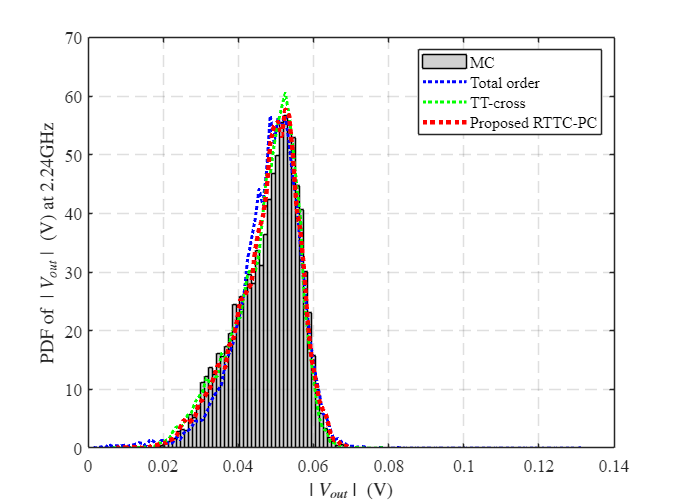

close all
pdf_freq_idx = 75;

f = figure(5);
Hmc = histogram( abs(testing_outs(:,pdf_freq_idx)) ,50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N_mc,edges] = histcounts(abs(vouts_total(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_mc,'b:','LineWidth',2)
[N_mc,edges] = histcounts(abs(vouts_tt_cross(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_mc,'g:','LineWidth',2)
[N_mc,edges] = histcounts(abs(vouts_Riemannian(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_mc,'r:','LineWidth',3)

xlabel('$\mid V_{out} \mid$ (V)','interpreter','LaTex');
ylabel(['PDF of $\mid V_{out} \mid$ (V) at ' num2str(round(fpoints(pdf_freq_idx)/scale,2)) 'GHz'], 'interpreter','LaTex');
grid on
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
legend('MC', 'Total order','TT-cross','Proposed RTTC-PC')

f.Position = [100 100 675 500];